## Set up the Import Options and import the data

opts = delimitedTextImportOptions("NumVariables", 7);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["Throttle", "PowerOut", "Voltage", "Ripple", "Current", "Temperature", "Speed"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
data_esc = readtable("/home/deekshakota/Desktop/PX4-Autopilot/FLIGHT_TEST_DATA/flight test day2/combined_flight1/Copy_of_first_elevator_D2_S_Sine.csv", opts)

data_esc = 8659×7 table
    Throttle    PowerOut    Voltage    Ripple    Current    Temperature    Speed
    ________    ________    _______    ______    _______    ___________    _____

     0.9937        0         11.92       0          0          90.2          0  
     0.9937        0         12.07       0          0          88.7          0  
     0.9937        0         12.07       0          0          90.2          0  
     0.9937        0         12.07       0          0          88.7          0  
     0.9937        0         12.07       0          0          90.2          0  
     0.9937        0         12.07       0          0            91          0  
     0.9937        0         12.07       0          0          90.2          0  
     0.9

## Data analysis

start_time = datetime('2023-03-25 00:00:00.148000');
end_time = datetime('2023-03-25 00:14:25.996000');
Ts = seconds(1/10);   %10Hz
% Generate range of datetime values with fixed sample time
Time = (start_time:Ts:end_time)';

sync_data = timetable(Time,data_esc.Throttle,data_esc.Speed,'VariableNames',{'throttle','rpm'});
sync_data = rmmissing(sync_data)

sync_data = 8587×2 timetable
            Time            throttle    rpm
    ____________________    ________    ___

    25-Mar-2023 00:00:00     0.9937      0 
    25-Mar-2023 00:00:00     0.9937      0 
    25-Mar-2023 00:00:00     0.9937      0 
    25-Mar-2023 00:00:00     0.9937      0 
    25-Mar-2023 00:00:00     0.9937      0 
    25-Mar-2023 00:00:00     0.9937      0 
    25-Mar-2023 00:00:00     0.9937      0 
    25-Mar-2023 00:00:00     0.9937      0 
    25-Mar-2023 00:00:00     0.9937      0 
    25-Mar-2023 00:00:01     0.9937      0 
    25-Mar-2023 00:00:01     0.9937      0 
    25-Mar-2023 00:00:01     0.9937      0 
    25-Mar-2023 00:00:01     0.

## system identification

u = sync_data.throttle;
y = sync_data.rpm;
np = 1;
nz = 0;
data = iddata(y,u)

data =

Time domain data set with 8587 samples.
Sample time: 1 seconds                  
                                        
Outputs      Unit (if specified)        
   y1                                   
                                        
Inputs       Unit (if specified)        
   u1                                   
                                        


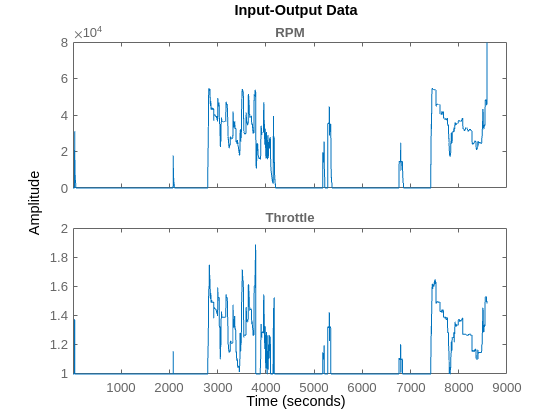

set(data,'InputName',{'Throttle'},'OutputName',{'RPM'})
plot(data)

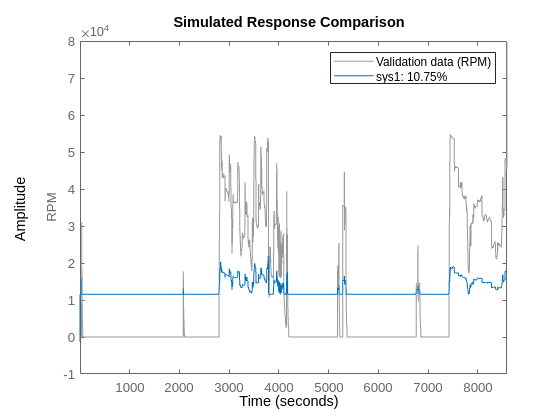

sys1= tfest(data,np,nz);
compare(data,sys1)